# Battery - modeling and SOC estimation

*Ing. David Vošahlík*

## Modeling

The modeling activity covered in this seminar will handle battery used in all types of powertrains (EV, BEV, PHEV, HEV, FCEV,etc.). Most of the chemical/physical phenomenas appearing in the batteries are similarly modeled for all battery types. Just the shapes and parameters are changing. Therefore, only one battery model will be introduced here. It will be so called *** 2 RC battery model.*** It is based on an equivalent circuit that represents the chemical and physical processes (like electrodes polarization, etc.)

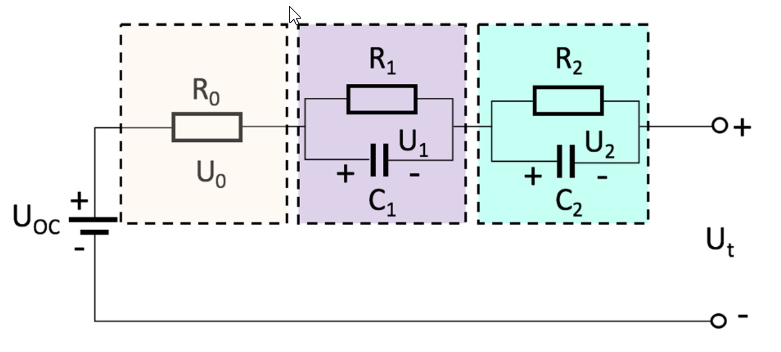


$$\begin{array}{l}
{\dot{\mathrm{U}} }_1 =-\frac{1}{R_1 C_1 }U_{1\;} +\frac{1}{\textrm{C1}}I\\
\dot{U_2 \;} =-\frac{1}{R_2 C_2 }U_2 +\frac{1}{C_2 }I\\
\dot{\textrm{SOC}} =-\eta \frac{1}{C}I\\
U_t =U_{\textrm{OC}} -U_1 \;-U_2 -{I\;R}_0 \;,
\end{array}$$


where I is the current flowing at the terminals, $\eta$ is the battery efficiency, $C$ is the battery capacity, and the other symbols meaning is explained in the figure above. The main parts are:

### Open Circuit Voltage

The $U_{\textrm{OC}}$ represents the battery open circuit voltage. A single cell open circuit voltage is shown in the figure for illustration. Depending on the chemistry used the shape of the curve can be changing but usually contains almost linear part in the middle and higly non-linear parts at the both almost depleted and almost full battery. It is usually represented as a function of SOC (State of Charge) or DOD (Depth of Discharge).

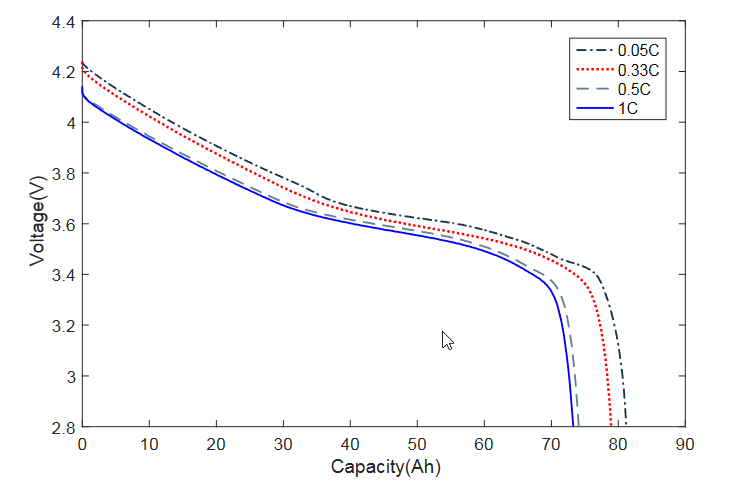

### Internal resistance

It is the internal resistance of the battery that is always present. Usually represented as a function of SOC or DOD. It can have different shapes for different chemistry.

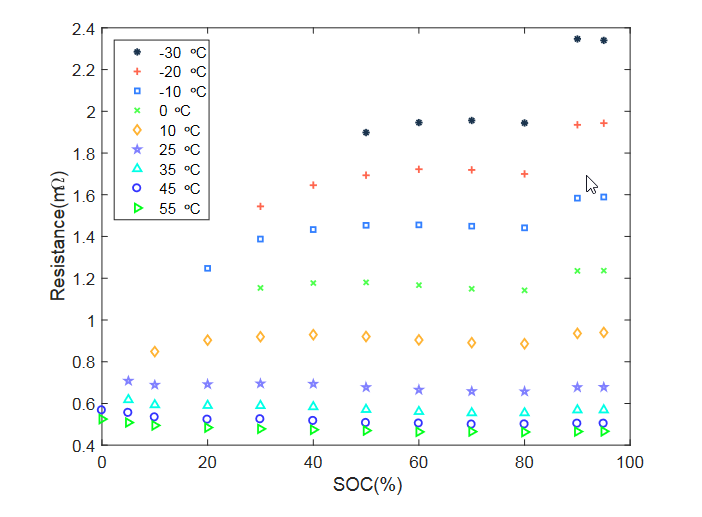

### RC circuit

The two RC circuits represent the chemical processes in the battery like electrodes polarization. The first time constant is tipically in range of 1 - 10 ms and the second one ranging approximately 50 ms.

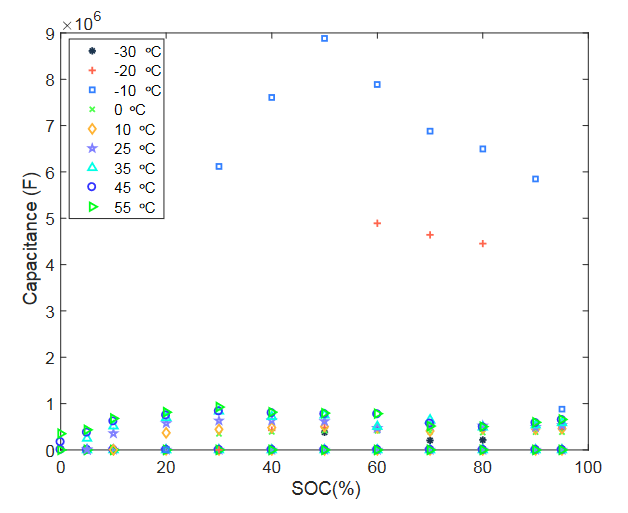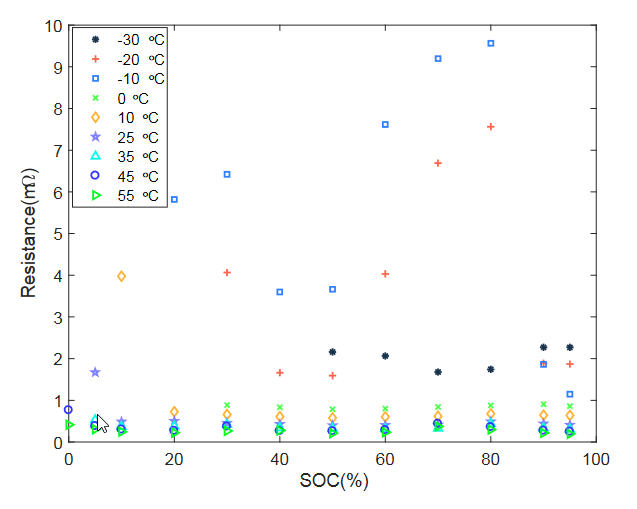

#### Your task

Your task will be to implement the 2 RC model in the prepared script. Simplifications of the individual curves using polynomials will be introduced in order to later use EKF (Extended Kalman Filter) for SOC estimation. Please fill the ***BatStateDerivative ***and ***BatOutput ***functions at the bottom of this live script.

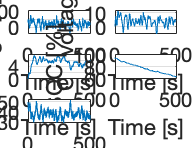

% Let's try how the Battery behaves
car = InitializeCar();              % Setup the constants
% Prepare the time vector
time = 0:0.1:500;
% Generate some random signal as input to the model
Current = 200*ones(1,numel(time)) + movmean(2000*randn(1, numel(time)), 100);
% Define model initial state
x0_bat = [0;0;95];
% Initialize the output vector
trmVolt = zeros(1,numel(time));
% solve the continuous time model using ode45 solver
[~,x_bat] = ode45(@(t,x) myode(t,x,time,Current, @(x, u) BatStateDerivative(x, u, car)), time, x0_bat);
x_bat = x_bat.';
% Define the process noise and measurement noise
Q = diag([0.02, 0.01, .1]);
R = 1;
Q_sqrt = chol(Q,'lower');
RSqrt = sqrt(R);
for i = 1:numel(time)
    % add the process noise to the state vector
    x_bat(:,i) = x_bat(:,i) + Q_sqrt*randn(3,1);
    % solve the output function with the measurement noise
    trmVolt(i) = BatOutput(x_bat(:,i), Current(i), car) + RSqrt*randn(1,1);
end
% Plot all the important signals
figure(1);
clf;
subplot(321);
plot(time, Current);
grid on;
xlabel('Time [s]');
ylabel('Current [A]');

subplot(322);
plot(time, x_bat(1,:));
grid on;
xlabel('Time [s]');
ylabel('C1 voltage [V]');

subplot(323);
plot(time, x_bat(2,:));
grid on;
xlabel('Time [s]');
ylabel('C1 voltage [V]');

subplot(324);
plot(time, x_bat(3,:));
grid on;
xlabel('Time [s]');
ylabel('SOC [%]');

subplot(325);
plot(time, trmVolt);
grid on;
xlabel('Time [s]');
ylabel('Terminal voltage [V]');

## SOC estimation

The SOC can be estimated in many ways. The first obvious thing is to measure the battery capacity and then count the charge (coulombs) that are going to the battery or out of it. Another approach is to use Kalman Filter or any similar algorithm. There are also other approaches like neural networks, but these are out of this course scope. Coulomb counting and Extended Kalman Filter (EKF) methods will be implemented in this seminar.

Take the simulation data from previous experiment. Compare two cases:

- exactly knowing the initial SOC

- Initial SOC is not know perfectly, e.g., the initial estimate is biased by 5%

### Coulomb counting

Implement coulomb counting method for SOC estimation for the scenarios mentioned above. Please fill the SOC_est vector.

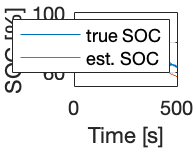

% Define the initial state
SOC0 = x0_bat(3);
% Initialize the estimated SOC vector
SOC_est = zeros(1, numel(time));
% Shift the initial estimated SOC -> The initial state is not known perfectly
SOC_est(1) = SOC0-5;
% Compute sampling time
dt = mean(diff(time));

for i = 2:numel(time)
   SOC_est(i) = SOC_est(i-1) - Current(i-1)*dt/car.Bat.C;
   
   % IMPLEMENT the Coulomb counting: SOC_est(i) = ...


end
% Plot the comparison of estimated and actual SOC
figure();
clf;
plot(time, x_bat(3,:));
hold on;
plot(time, SOC_est);
grid on;
xlabel('Time [s]');
ylabel('SOC [%]');
legend('true SOC', 'est. SOC');

### EKF

Now let's use more advanced technique like EKF (Extended Kalman Filter). As you may have not met the algorithm yet, it will be ready for you already implemented. There ar two matrices: Q - process noise and R - measurement noise. The theory says these should correspond to the noise values, which were added while generating the data. However, usually those are not known and the Q and R matrices are the main tuning knobs of the algorithm. The rule of thumb is here following. If the state variable is too much noisy, then lower down the diagonal element in Q corresponding to the state. If it is too slow and the dynamic behavior should be increased then raise the diagonal element in the matrix Q. If the measurement and EKF output are not matching as you want, then lower down the corresponding diagonal element in R. The more you lower down the R matrix value the more you "trust" the measurement and the EKF output will stick to the measured data (not good for noisy data) and vice versa. The EKF tuning is also depending on the ratio of both matrices Q and R. It is also not desirable to have ill-conditioned matrices Q and/or R and/or their ratio.

You also need a linearization of the system around operating point to obtain LTI system matrices A and C. The main part of the algorithm is already prepared. Your task will be to implement the so called jacobians (linearization of the system producing the matrices A and C). The functions you have to implement are continuous time ***dfdx*** and ***dgdx***.

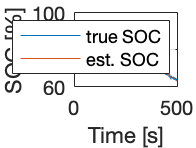

% Define the initial state for EKF
xhat = [0;0;SOC0 - 5];
% Define and tune the Q and R matrices used in the EKF
Q = diag([0.0001, 0.0001, .01]);
R = 10;
% Setup the initial covariance matrix
P = Q*5000;
% Shift the initial estimated SOC -> The initial state is not known perfectly
SOC_est(1) = SOC0 - 5;

% Initialize the output vector and first sample
yhat = zeros(1, numel(time));
yhat(1) = BatOutput(xhat, Current(1), car);

for k=2:length(time)
    
    % Data step EKF
    C = dgdx(xhat);                                                     % matrix C(t) approx
    L = P*C'/(C*P*C' + R);                                              % kalman gain for data step
    P = P - L*(C*P*C' + R)*L';                                          % P(t|t) estimate
    yhat(k) = BatOutput(xhat, Current(k), car);                     % Compute the estimated output
    xhat = xhat + L*(trmVolt(k) - BatOutput(xhat, Current(k), car));% xhat(t|t) estimate
    % Fill in the estimated SOC value to plot it later
    SOC_est(k) = xhat(3);

    %Time step
    A = dfdx(xhat, Current(k), car, dt);                                % matrix A(t) approx
    xhat = xhat + BatStateDerivative(xhat, Current(k), car)*dt;         % xhat(t+1|t) estimate
    P = A*P*A' + Q;                                                     % P(t+1|t) estimate
end

% Plot the comparison of estimated and actual SOC
figure();
clf;
plot(time, x_bat(3,:));
hold on;
plot(time, SOC_est);
grid on;
xlabel('Time [s]');
ylabel('SOC [%]');
legend('true SOC', 'est. SOC');

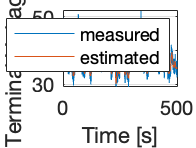


% Plot the comparison of estimated and actual output
figure();
clf;
plot(time, trmVolt);
hold on;
plot(time, yhat);
grid on;
xlabel('Time [s]');
ylabel('Terminal Voltage [V]');
legend('measured', 'estimated');

function [xDot_bat] = BatStateDerivative(x_bat, u_bat, car)
% State derivative function for battery - continuous time dynamics
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the input [Current [A]]
% car - structure with the parameters. Check InitializeCar.m function


% Implement the continuous time dynamic equations. Use the constants defined in the car.Bat
    C1 = car.Bat.C1;
    C2 = car.Bat.C2;
    eta = car.Bat.eta;
    C = car.Bat.C;
    R1 = car.Bat.R1;
    R2 = car.Bat.R2;

    B = [1/C1;1/C2;-eta/C];
    A = [-1/(R1*C1) 0 0; 0 -1/(R2*C2) 0; 0 0 0];
    xDot_bat = A*x_bat + B*u_bat;

end

function [y_bat] = BatOutput(x_bat, u_bat, car)
% output function for battery - continuous time dynamics
% x_bat - is the battery state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the battery input [Current [A]]
% y_bat - is the battery output [Terminal voltage [V]]
% car - structure with the parameters. Check InitializeCar.m function
    R0 = car.Bat.R0;
    D = -R0;
    C = [-1 -1 0];
    y_bat = ocv(x_bat(3)) + C*x_bat + D*u_bat;
% Compute the terminal voltage output. Use the constants defined in the car.Bat
end


function voltage = ocv(SOC)
% Copmute the open circuit voltage [V] for the provided SOC [%]
voltage = 38 + 0.295*SOC - 0.01*SOC^2 + 1.9694e-04*SOC^3 - 1.652e-06*SOC^4 + 5.234e-09*SOC^5;
end

function A = dfdx(x, u, car, Ts)
% Compute the discrete time jacobian of the system derivative function with respect to state (system matrix A)
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
    C1 = car.Bat.C1;
    C2 = car.Bat.C2;
    R1 = car.Bat.R1;
    R2 = car.Bat.R2;
    A = [-1/(R1*C1) 0 0; 0 -1/(R2*C2) 0; 0 0 0];
    A = expm(A*Ts);
% IMPLEMENT the discrete time matrix A calculation. A = ...

end

function C = dgdx(x,u,car)
% Compute the discrete time jacobian of the output function with respect to state (system matrix C)
    SOC = x(3);
    C = [-1 -1 0.295-0.02*SOC+3*1.9694e-04*SOC^2-4*1.652e-06*SOC^3+5*5.234e-09*SOC^4];
% IMPLEMENT the discrete time matrix C calculation. C = ...
end

function dxdt = myode(t,x,ut,u, fun)
% function wrapper for the ode45 solver so that it is able to solve the differential equations
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end
